addpath Function\
addpath Template_data\

** Copy your code here**

addpath Function\
addpath Semester_2nd_data\

x=load("1series_2.txt");
y=load("1series_3.txt");
 
% One-side:  0.95  1-0.05
% Two-side:  u2u("95s")  u2u("5a")
conf=confidence_tool();

[sig1,sig2,e1,e2]=deal(0.0015,0.0015,34,34);
[mean1,s1,f1]=conf.mean_s_dof(x);
[mean2,s2,f2]=conf.mean_s_dof(y);

[a,b]=conf.get_interval_f(u2u("99s"),s1,s2,f1,f2);

The interval boundary is [0.4248,1.954]
The confidence Level = 99.00%, Error probability = 1.00%


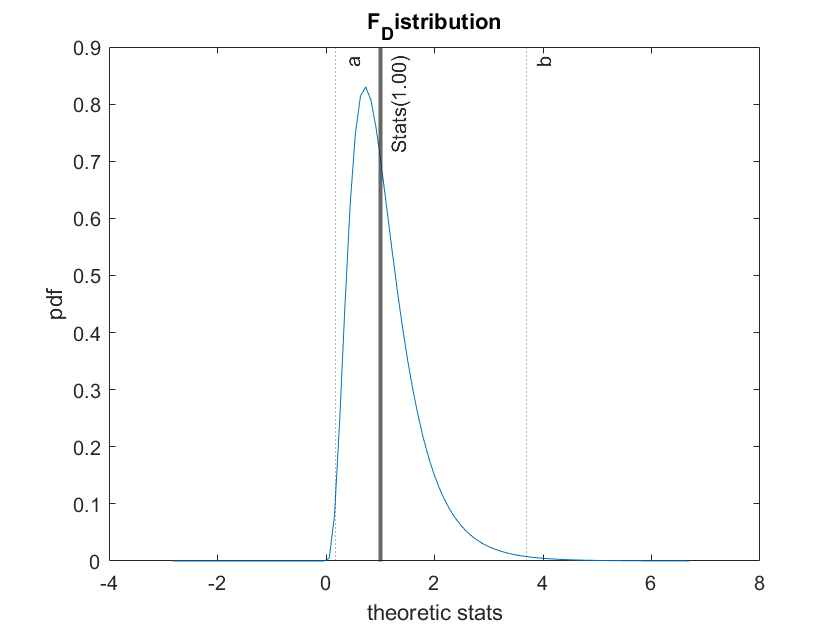

One Side: The confidence Level = 99.50%, Error probability = 0.50%
Two Side: The confidence Level = 99.00%, Error probability = 1.00%
Fails to reject the H0


stats=conf.statistic_test_f(u2u("99s"),sig1,sig2,s1,s2,f1,f2);


[a,b]=conf.get_interval_chi(u2u("99s"),s1,f1);

The interval boundary is [0.003908,0.00106]
The confidence Level = 99.00%, Error probability = 1.00%


[a,b]=conf.get_interval_chi(u2u("99s"),s2,f2);

The interval boundary is [0.003274,0.001525]
The confidence Level = 99.00%, Error probability = 1.00%


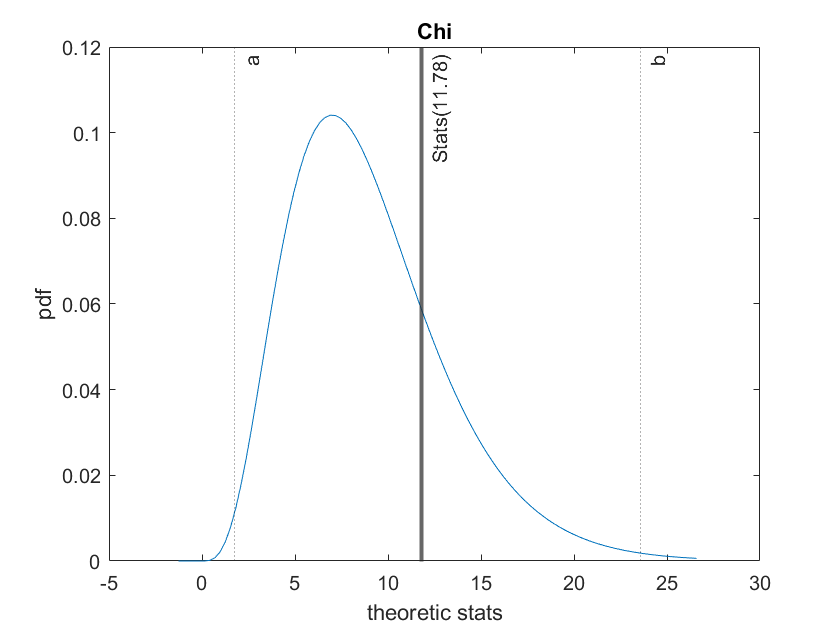

One Side: The confidence Level = 99.50%, Error probability = 0.50%
Two Side: The confidence Level = 99.00%, Error probability = 1.00%
Fails to reject the H0


stats=conf.statistic_test_chi(u2u("99s"),sig1, s1,f1);

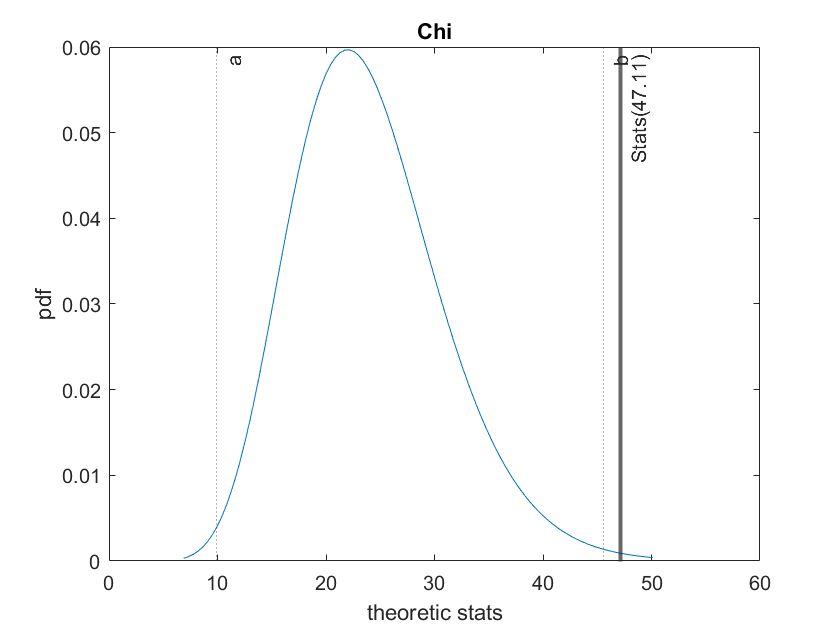

One Side: The confidence Level = 99.50%, Error probability = 0.50%
Two Side: The confidence Level = 99.00%, Error probability = 1.00%
Rejects the H0, significant bigger then


stats=conf.statistic_test_chi(u2u("99s"),sig2, s2,f2);



%Two side : u("99s") = u("1a") = 0.995
%One side : a=2*a   s=100-2*a  then same with two side